# Eigenanalysis Applications

 This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

 If you find the MATLAB coding in this script to be challenging, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## **Vibrating masses**

**Physical system and equations of motion**

Consider a system of $n$ masses connected by strings with uniform tension $T$ and horizontal distance $l$ between each mass.

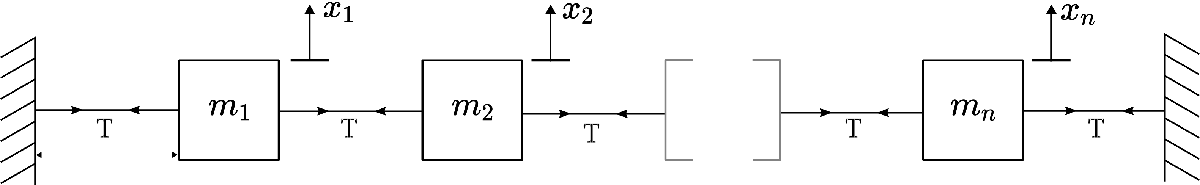

*System of equally spaced connected masses*

Each mass has a mass $m_i$ and a vertical displacement $x_i$ from a reference position. For simplicity, masses are assumed to be displaced only in the vertical direction. You can draw a free body diagram for $i^{th}$ mass and use it to derive the equations of motion.

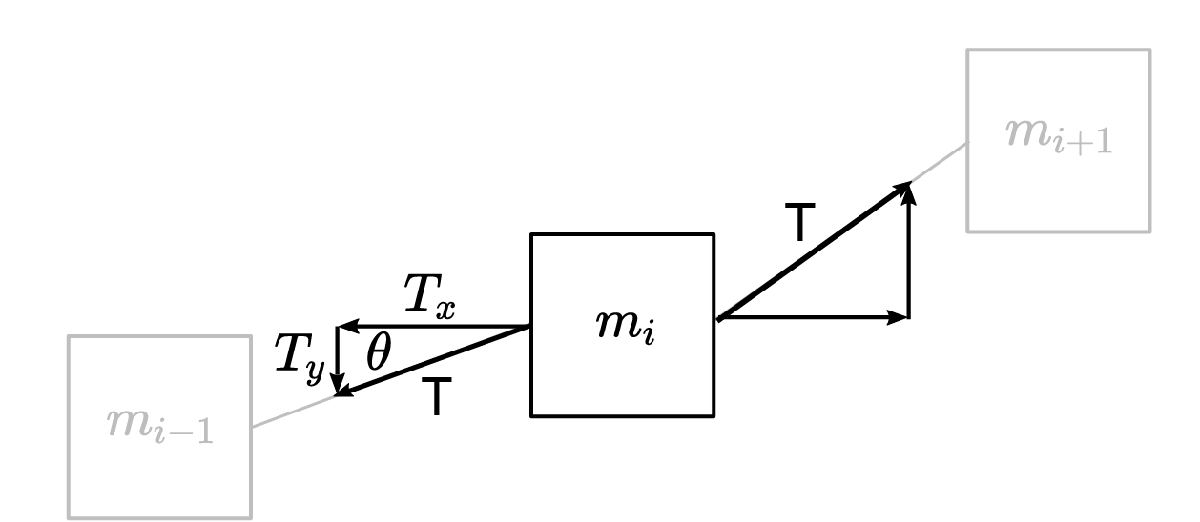

*Free body diagram for the *$i^{th}$* mass*

The angle $\theta$ can be related to the displacements. Note that in this calculation the displacement is assumed to be small, so that the horizontal distance between the masses $\approx l$.


$$\sin \theta = \frac{x_i - x_{i-1}}{l}$$


The force acting in the $y$-direction is


$$\begin{array}{rl} T_y &= T \sin \theta \\ &= \frac{T}{l} (x_i - x_{i-1}) \end{array}$$


Performing the same analysis on the other side of the mass yields a similar result. Applying Newton's second law yields:


$$\begin{array}{rl}
m_i \ddot{x}_i &= \frac{T}{l}( - x_i + x_{i-1} )  + \frac{T}{l}(x_{i+1} - x_{i} ) 
\\
m_i \ddot{x}_i &= \frac{T}{l}( x_{i-1} - 2x_i + x_{i+1} )
\end{array}$$


Note that the double dot notation represents the second derivative with respect to time: $\ddot{x}_i = \frac{d^2 x_i}{dt^2}$.

For simplicity, assume $m_i = T = l = 1$, yielding:


$$\begin{array}{rl}
\ddot{x}_i &=  x_{i-1} - 2x_i + x_{i+1} 
\end{array}$$


for each mass. Note that for the first and last mass the equations are identical but lack the displacements of the missing neighbor:


$$\begin{array}{rl}
\ddot{x}_1 &=  - 2x_i + x_{i+1} 
\\
\ddot{x}_n &=  x_{n-1} - 2x_n 
\end{array}$$


**Matrix form of the equations of motion**

To represent this system in matrix form, define the vector of displacement variables:

$\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$.

Using this definition, you can write the equations of motion in the form:


$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


  **Task. **Define the number of masses in the system, `n` (you will use this value in the remainder of the example). 

n = 4;      % Number of masses
 

** Exercise**. Based on the definition of $\mathbf{x}$ and the ODE system:


$$\begin{array}{rl}
&\ddot{x}_1 =  - 2x_i + x_{i+1} 
\\
&\ddot{x}_i =  x_{i-1} - 2x_i + x_{i+1} 
\\
&\ddot{x}_n =  x_{n-1} - 2x_n 
\end{array}$$


what will the form of the coefficient matrix $\mathbf{A}$ be in the matrix form of the ODE system, $\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$?

showSolution = false;
if(showSolution)
    AForm(n)
end

** Exercise**. Define the coefficient matrix $\mathbf{A$ in MATLAB as a numeric matrix for an arbitrary number of masses $n$.

**Hint**: Use the [`diag`](https://www.mathworks.com/help/matlab/ref/diag.html) function three times to create three diagonal matrices and sum the result with the correct coefficients. The size of the system is stored in the variable `n`.

% Define the matrix A


**Solution to the ODE system in MATLAB**

The ODE system 


$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


is solved here using a numeric ODE solver. In this process, the ODE is integrated to yield a solution $\mathbf{x}(t)$ given initial conditions $\mathbf{x}(0)$ and $\dot\mathbf{x}(0)$.

  **Task. **Run the section to see the solution. Notice how compact the ODE implementation is by examining the function `odeStringMasses`. Matrix representations, like this one, are effective for writing concise code.

x01 = 0.2;   % Initial displacement of the first mass
tf =10;     % Duration of the simulation
 

x0 = zeros(n,1);
x0(1) = x01;
tlim = [0 tf]; 
[t,x,xdot] = solveMassesODE(x0,tlim,n);

figure("Position",[100 200 1000 400])
plot(t,x)
xlabel("t")
ylabel("x(t)")
legend("x_{" + strsplit(num2str(1:n)) + "}","Location","EastOutside")

  **Try**. 

- Adjust the number of masses `n` above and rerun the simulation. Does the natural oscillation frequency change?

- Adjust the initial displacement and duration of the simulation. What happens as $t$ becomes large?

**Visualize the motion**

The graph of displacements can be difficult to relate to physical experience. Run this section to visualize the motion.

x01 = 0.35;   % Initial displacement of the first mass
tf =10;     % Duration of the simulation
Nframes = 110; % Adjust the number of frames to speed up or slow down the animation
 


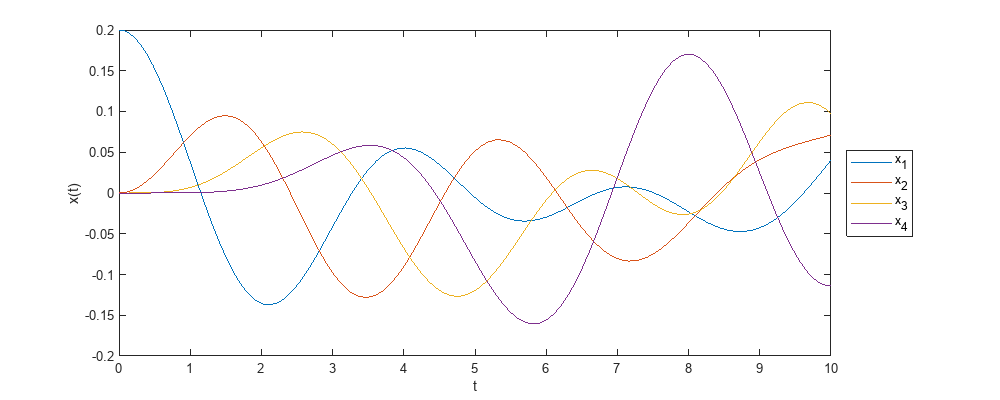

x0 = zeros(n,1);
x0(1) = x01;
tlim = [0 tf]; 

[t,x,xdot] = solveMassesODE(x0,tlim,n); 
animateODEMasses(t,x,Nframes)

**Eigenvectors and natural oscillation modes**

The natural modes of oscillation of the connected mass system can be identified by computing the eigenvectors of the coefficient matrix `A`.

% The coefficient matrix
A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1)

** Exercise**. Compute and visualize the eigenvectors of the coefficient matrix.

  **Task**. Compute the eigen decomposition of $\mathbf{A$ in MATLAB. Store the outputs in `V` and `D`.

  **Try**. Each eigenvector represents the displacements of the masses according to a natural vibration mode. This section visualizes the eigenvectors with the masses shown. Adjust the mode index to view the natural vibrational modes.

modeIndex = 1; % The mode index must be <= the number of masses
visualizeMasses(modeIndex,n)

 **Reflect. **

- Based on the simulation output, which mode do you think is dominant in the simulation generated above?

**Computation of the modes present in the ODE solution**

The eigenvectors provide an alternative basis for the motion of masses. You can compute which modes are present in the simulation by expressing the solution in terms of the eigenvector basis:


$$\mathbf{x} = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


The coefficients $\mathbf{b}$ determine the weights of each mode.

In matrix form, this linear combination is:


$$\mathbf{x} = \mathbf{V} \mathbf{b}$$


where $\mathbf{V}$ is the eigenvector matrix in the eigen decomposition. To solve for the mode coefficients at any time $t$, you can compute the matrix solution for $\mathbf{b}$.

** Exercise**. Solve for the mode coefficients $\mathbf{b}$ at the last time step in the simulation. 

**Hint**: To access the values of $\mathbf{x}$ in the last time step, use:

  **Try**. Run this section to plot the mode coefficients over time in the solution. The mode coefficients are computed at each time step below.

figure("Position",[100 200 1000 400]) 
b = zeros(size(x));
[V,~] = eig(A);
for k = 1:length(t)
    b(k,:) = V\x(k,:)'; % Compute mode coefficients at each time step
end
plot(t,b) % Plot b here
legend("b_{" + strsplit(num2str(1:n)) + "}","Location","EastOutside") % This adds a legend to the plot

 **Reflect. **

- Does there appear to be a dominant mode present in this particular solution? There may not be. 

- Do different modes have different periods of oscillation?

**Eigenmode solutions**

In the above sections, you analyzed a solution using eigenvectors. It is also possible to use the eigenvector basis to construct the initial condition for the model. To do so, you can set the initial displacement of the system to a sum of the natural modes:


$$\mathbf{x}_0 = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


The system will continue to oscillate with those natural modes indefinitely as there is no damping term in the equation. 

  **Task**. Define a new $n$-element mode coefficient vector `b` to determine which modes will be present in the simulation. You can vary the values of `b` to emphasize different solution modes.

A =     -2     1     0     0
     1    -2     1     0
     0     1    -2     1
     0     0     1    -2


  **Task**. Compute the initial condition vector `x0` based on the coefficient vector `b` and the eigenvector matrix `V`.

**Visualize the motion**

Check the box to run this section, compute the  ODE solution, and visualize the solution.

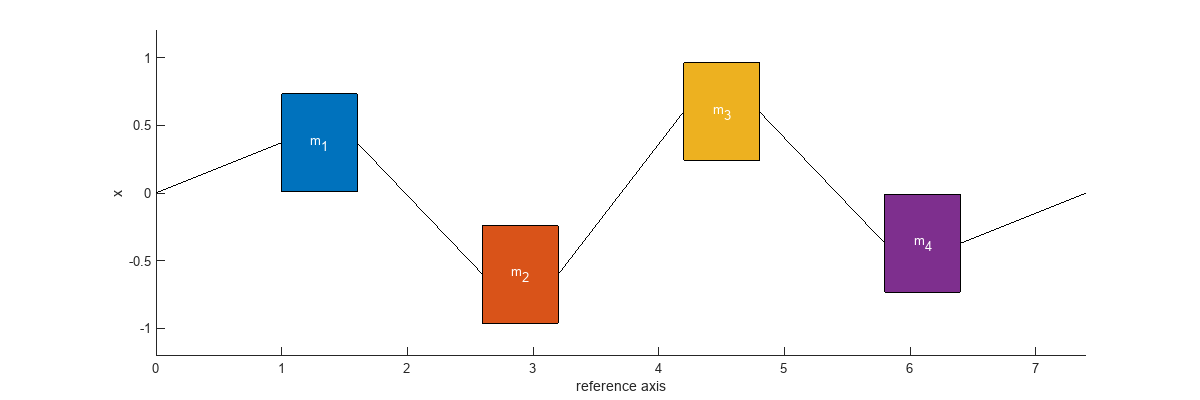

tf =20;     % Duration of the simulation
Nframes = 130; % Adjust the number of frames to speed up or slow down the animation

 

tlim = [0 tf]; 
[t,x,xdot] = solveMassesODE(x0,tlim,n);
animateODEMasses(t,x,Nframes)

 **Reflect. **

- Can you recognize each eigenmode individually?

- What happens when you change the relative scale factors (i.e., the eigenvector coefficients $b_i$) for different eigenmodes?

- Is energy transferred between eigenmodes?

- Go back and alter the coefficient vector $\mathbf{b}$ so that the initial condition $\mathbf{x}_0$ contains different modes. Are the changes reflected in the dynamic behavior?

## Risk assessment using a Markov chain 

**Background**

Consider a car insurance company that has classified clients using five risk categories.

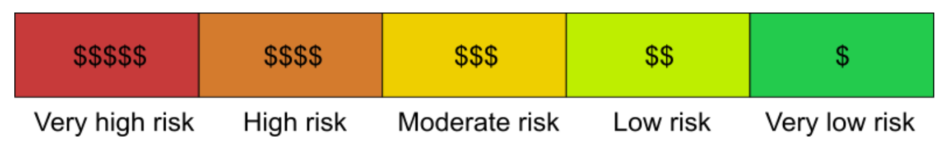

*Risk categories. High risk clients pay higher premiums because they are more likely to require a payout on a claim.*

Each year, the risk of a client is reassessed. Clients will be moved between categories based on their history. For example:

- being at fault in an accident will move a client into a higher risk category

- having a year without an incident could move the client into a lower risk category.

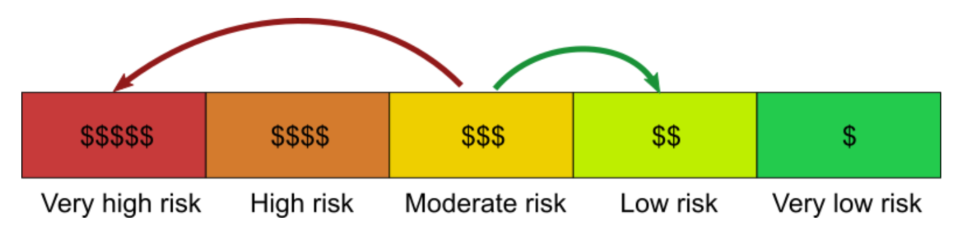

*Two possible transitions of clients between categories.*

A Markov chain can be used to model how the pool of clients will change based on the history of how clients have moved between categories in the past. The client history is represented as a probability (over 1 year) that a client will move into another category or stay in the same category.

The goal of the model is to determine how the distribution of clients in different risk categories will change in the future.

**Transitions**

Let the fraction of clients in each category be modeled by


$$\mathbf{r} = \left( \matrix{ r_1 \cr r_2 \cr r_3 \cr r_4 \cr r_5 } \right)$$


Each variable $r_i$ represents the fraction of clients in each risk category (with all clients $= \sum_i r_i = 1$). The lowest risk being represented by $r_5$ and $r_1$ indicating very high risk. Each year, a client has a probability that they will move into another category or remain in that same category. 

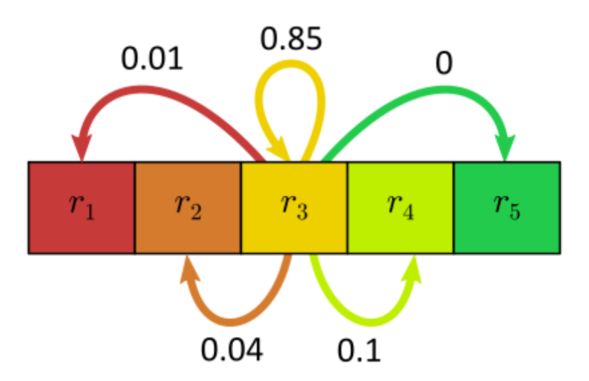

*Likelihoods for *$r_3$* client transitions. The majority (85%) remain in *$r_3$ *each year. No clients are moved into *$r_5$*, since they will have to pass through the low-risk category (*$r_4$*) first.*

Notice that the total probability of transitions out of $r_3$ are equal to 1. These transitions are just one set of probabilities. In fact, there are 5 sets of transitions: one set for each category.

**Transition matrix**

The* transition matrix *$\mathbf{P}$ models how clients will move between all 5 categories each year. To find the new classification of the clients after one year, multiply the transition matrix by the current state vector $\mathbf{r}$:


$$\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$$


 The transition matrix is the heart of a Markov chain model. $\mathbf{P}$ has the form

P = sym("p",[5 5])
 

Each column determines the probabilities of transitioning out of one risk group and into another. For example, the third column determines the likelihood of transitions out of the $r_3$ client class:

- $p_{1,3}$ = probability of transition $r_3 \rightarrow r_1$

- $p_{2,3}$ = probability of transition $r_3 \rightarrow r_2$

- $p_{3,3}$ = probability of transition $r_3 \rightarrow r_3$ (staying in the same category)

- $p_{4,3}$ = probability of transition $r_3 \rightarrow r_4$

- $p_{5,3}$ = probability of transition $r_5 \rightarrow r_4$

This works because the matrix-vector multiplication $\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$ yields:

r = sym("r",[5,1]);
rnew = P*r

In this result, the first row sums the product of the probabilities $p_{1,i}$ (the probability of moving into $r_1$ from $r_i$) and $r_i$ (the current fraction of clients in the $i^{th}$ category). That sum yields the updated fraction of clients in the $r_1$ category. The other rows have a parallel interpretation.

**Constructing a transition matrix**

To implement the specific transitions shown above for the $r_3$ group, put the transitions values into the third column of the transition matrix $\mathbf{P}$. 

*Likelihoods for *$r_3$* clients to move into a category over one year.*

P(:,3) = [0.01 0.04 0.85 0.1 0]
 

In general, the transition probabilities are estimated from historical data. If similar trends continue in the future, these transitions can make predictions about how clients will change risk categories in the future.

  **Task. ** Use the transitions shown in the image below to set the transitions out of $r_1$ in the matrix `P`.

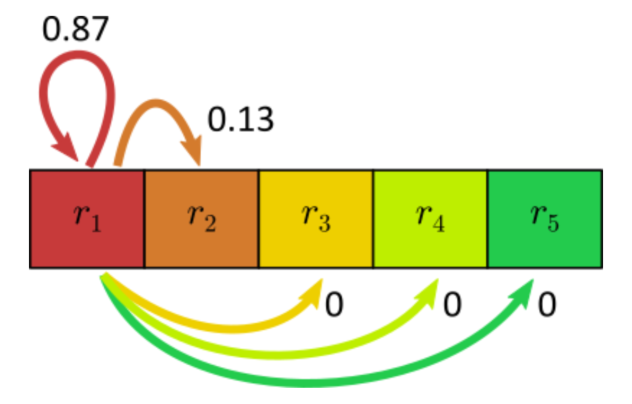

*Likelihoods for *$r_1$* clients. The only path out is to be moved into the high-risk category.*

**Hint**: Set the first column of the matrix using `P(:,i) = [values]`. The "`:`" operator selects all the rows. The index `i `determines the column index.

% Write code to set the first column of P here


The rest of the transitions have been filled in below. 

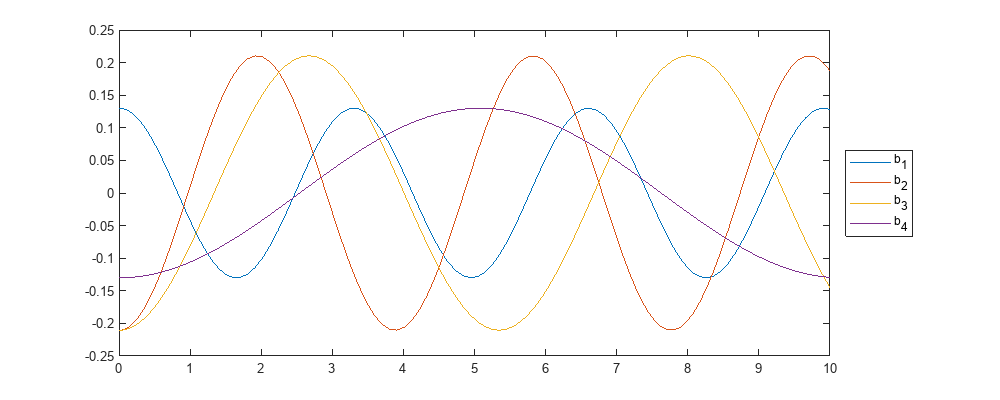

P = [0.87 0.05 0.01 0.01 0.01;
     0.13 0.83 0.04 0.02 0.01;

     0.00 0.12 0.85 0.05 0.02;
     0.00 0.00 0.10 0.90 0.03;
     0.00 0.00 0.00 0.02 0.93]

  **Try. **A digraph can visualize the transition matrix. Run this section to generate the digraph.

 
figure("position",[1 1 700 650])
G = digraph(P',["r_1","r_2","r_3","r_4","r_5"]);
plot(G,"linewidth",10*sqrt(G.Edges.Weight))

 **Reflect**

- Which transitions have the highest probability?

- Where are these high probability transitions represented in the transition matrix?

**Applying a transition matrix**

Suppose that, initially, the clients are equally distributed in all categories. 

  **Task. **Define a column vector $\mathbf{r}$ that represents this situation (note that you should have $\sum_i r_i = 1$).

  **Task. **After one year, what will the new client classification be? Use matrix multiplication.

Repeated transition matrix applications will yield distributions of clients' risk categories after longer periods of time.

  **Task. **After 10 years, what will the client risk distribution be?

  **Task. **After 100 years, what will the client risk distribution be?

 **Reflect**

- Which categories end up with the largest share of clients? Which have the smallest share?

- From a business standpoint, is this long-term distribution of clients desirable?

- Try starting with a different initial set of clients, $\mathbf{r}$. How does this affect the long-term distribution?

**Eigenanalysis**

You can compute and understand the long-term behavior of a Markov chain in terms of its eigenvalues and eigenvectors. Recall that a non-defective square matrix can be diagonalized by computing its eigen decomposition:

$\mathbf{P} =\mathbf{V \Lambda V}^{-1} $.

This implies that for the update after one year:

$\mathbf{r}_{(1)} = \mathbf{V \Lambda V}^{-1} \mathbf{r}$.

To compute the state distribution after $n$ years, multiply by the transition matrix $n$ times:


$$\begin{array} {rl}
\mathbf{r}_{(n)} &= ( \mathbf{V \Lambda V}^{-1} )^n\mathbf{r}
\\
  &= (\mathbf{V \Lambda V}^{-1} )(\mathbf{V \Lambda V}^{-1} )\ldots (\mathbf{V \Lambda V}^{-1} )\mathbf{r}
\\
  &= \mathbf{V \Lambda}^n \mathbf {V}^{-1}  \mathbf{r}
\end{array}$$


** Exercise**. Compute the eigen decomposition of $\mathbf{P}$ and store the outputs in `V` and `D`. Use these matrices to evaluate the risk distribution $\mathbf{r}$ after 100 years.

 % Initial distribution of clients: 20% in each category
 r = [0.2 0.2 0.2 0.2 0.2]'
% Compute r(100) here



**Limit behavior**

You can understanding the limiting behavior of the Markov chain model more directly by examining the eigenvalues contained in $\mathbf{\Lambda}$. It can be shown that the eigenvalues of a transition matrix have the property: $\lambda \leq1$. Notice that this is true for this model:

[~,D] = eig(P)

Using this property, you can show that:


$$\lim_{n\rightarrow \infty} \mathbf{\Lambda}^n = 
\left(\begin{array}{ccccc}
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0
\end{array}\right)$$


  **Task. **Compute the limiting behavior as $n \to \infty$ of the system:


$$\begin{array} {rl}
\mathbf{r}_{(n)} = \mathbf{P}^{n}  \mathbf{r}
\end{array}$$
    

by computing the matrix $\mathbf{P}_\infty$ as

$\mathbf{P}_\infty =   \lim_{n\rightarrow \infty} \mathbf{V \Lambda}^n \mathbf {V}^{-1}$.    

Store the result in `Pinf`.

  **Task. **Compute the limit distribution


$$\begin{array} {rl}
\mathbf{r}_{(\infty)} = \mathbf{P}^{\infty}  \mathbf{r}
\end{array}$$
    

Store the result in `rinf`.

rinf = [];

$$P = \left(\begin{array}{ccccc} p_{1,1} & p_{1,2} & p_{1,3} & p_{1,4} & p_{1,5}\\ p_{2,1} & p_{2,2} & p_{2,3} & p_{2,4} & p_{2,5}\\ p_{3,1} & p_{3,2} & p_{3,3} & p_{3,4} & p_{3,5}\\ p_{4,1} & p_{4,2} & p_{4,3} & p_{4,4} & p_{4,5}\\ p_{5,1} & p_{5,2} & p_{5,3} & p_{5,4} & p_{5,5} \end{array}\right)$$

Run this section to plot the limit distribution as a bar graph using the [`bar`](https://www.mathworks.com/help/matlab/ref/bar.html) function.

 
figure("position",[1 1 500 300])
bar([r,rinf])

$$rnew = \left(\begin{array}{c} p_{1,1}\,r_{1}+p_{1,2}\,r_{2}+p_{1,3}\,r_{3}+p_{1,4}\,r_{4}+p_{1,5}\,r_{5}\\ p_{2,1}\,r_{1}+p_{2,2}\,r_{2}+p_{2,3}\,r_{3}+p_{2,4}\,r_{4}+p_{2,5}\,r_{5}\\ p_{3,1}\,r_{1}+p_{3,2}\,r_{2}+p_{3,3}\,r_{3}+p_{3,4}\,r_{4}+p_{3,5}\,r_{5}\\ p_{4,1}\,r_{1}+p_{4,2}\,r_{2}+p_{4,3}\,r_{3}+p_{4,4}\,r_{4}+p_{4,5}\,r_{5}\\ p_{5,1}\,r_{1}+p_{5,2}\,r_{2}+p_{5,3}\,r_{3}+p_{5,4}\,r_{4}+p_{5,5}\,r_{5} \end{array}\right)$$

set(gca,"xticklabel","r_" + strsplit(num2str(1:5)))
ylabel("Fraction of clients")
xlabel("Risk category")
title("$r_\infty$","Interpreter","latex")
legend("r_0","r_\infty")

 **Reflect**

- What is the relationship between the starting distribution $\mathbf{r}_0$ and the limit distribution? Note that $\mathbf{P}_{\infty}$ defines this relationship.

- What is the business significance of $\mathbf{r}_\infty$?

Supporting functions for the connected masses application

function [t,x,xdot] = solveMassesODE(x0,tlim,n)

$$P = \left(\begin{array}{ccccc} p_{1,1} & p_{1,2} & \frac{1}{100} & p_{1,4} & p_{1,5}\\ p_{2,1} & p_{2,2} & \frac{1}{25} & p_{2,4} & p_{2,5}\\ p_{3,1} & p_{3,2} & \frac{17}{20} & p_{3,4} & p_{3,5}\\ p_{4,1} & p_{4,2} & \frac{1}{10} & p_{4,4} & p_{4,5}\\ p_{5,1} & p_{5,2} & 0 & p_{5,4} & p_{5,5} \end{array}\right)$$

% This function solves the ODE with n masses
    xdot0 = zeros(n,1);
    y0 = [xdot0;x0];
    
    A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
    odeFunc = @(t,y)odeStringMasses(t,y,A,n);
    [t,y] = ode45(odeFunc,tlim,y0);
    
    xdot = y(:,1:n);
    x = y(:,n+1:2*n);
end

function [dydt] = odeStringMasses(t,y,A,n)
% The second-order system has been reduced to a system of first-order
% equations: the variable y =[u;x] where u = x_dot.
    u = y(1:n);

P =     0.8700    0.0500    0.0100    0.0100    0.0100
    0.1300    0.8300    0.0400    0.0200    0.0100
         0    0.1200    0.8500    0.0500    0.0200
         0         0    0.1000    0.9000    0.0300
         0         0         0    0.0200    0.9300


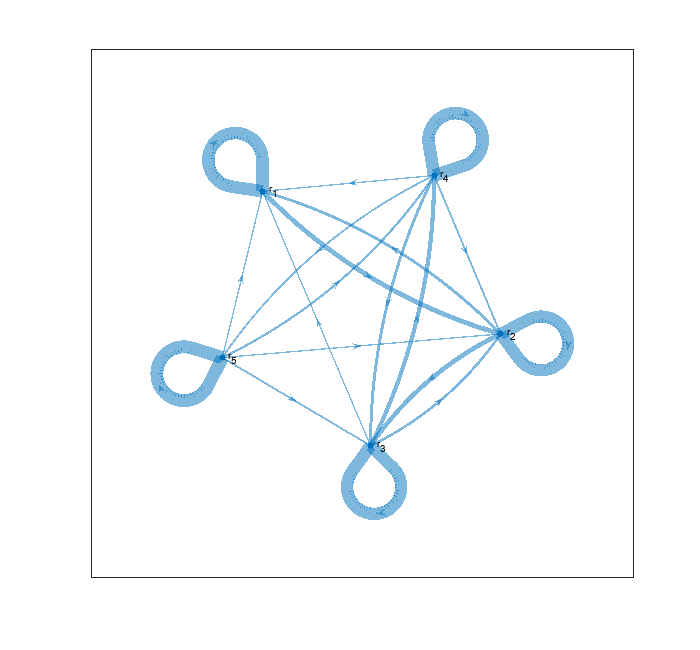

    x = y(n+1:2*n);
    x_dot = u;
    u_dot = A*x;
    dydt = [u_dot;x_dot];    
end


function AForm(n)
% This computes the correct form for the tridiagonal matrix
    A = sym(diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1))
end

function animateODEMasses(tin,xin,Nframes) 
% This function plots the ODE result 

    Nmass = size(xin,2); % Number of masses
    t = linspace(tin(1),tin(end),Nframes);
    x = interp1(tin,xin,t);
    
    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 0.6; % Mass width
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    xub = max(abs(x),[],"all")*2;
    h = w*(1200/325)*(2*xub/umax); % Height of masses
 
    % Loop to create the animation
    f = figure("Visible","On");    
    set(gcf,'position',[100 200 1200 800])   
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        for k = 1:Nmass

r =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


            % Plot masses
            umk = spacing*k -w;
            xm = x(j,k);
            rectangle("Position",[umk x(j,k)-h/2 w h],"FaceColor",colors(k,:))
            text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
                "center","color","w","fontsize",10)
            % Plot strings

D =     0.7424         0         0         0         0
         0    0.8140         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.8965         0
         0         0         0         0    0.9271


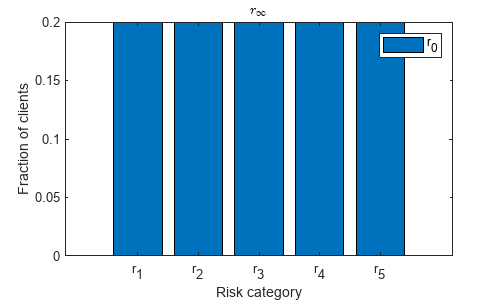

            if(k == 1)
                plot([umk-spacing+w, umk],[0,x(j,k)],'k')
            else
                plot([umk-spacing+w, umk],[x(j,k-1),x(j,k)],'k')
            end
        end
        % Last string
        umk = umax;
        plot([umk-spacing+w, umax],[x(j,k),0],'k')

        hold off
        axis([0 umax -xub xub])
        ylabel("x")
        xlabel("reference axis")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"ko","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x(t) ")

        hold off
        box off
        drawnow
    end
    close(f);
end

function visualizeMasses(modeIndex,n)
% This function visualizes the masses with positions defined in x

    % The coefficient matrix
    A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
    [V,~] = eig(A);
    x = V(:,modeIndex);

    Nmass = length(x); % Number of masses
    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 0.6; % Mass width
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    
    xub = max(abs(x),[],"all")*2;
    h = w*(1200/325)*(2*xub/umax); % Height of masses
 
    % Loop to create the animation
    figure;
    set(gcf,'position',[100 200 1200 400])   
    hold on
    for k = 1:Nmass
        % Plot masses
        umk = spacing*k -w;
        xm = x(k);
        rectangle("Position",[umk x(k)-h/2 w h],"FaceColor",colors(k,:))
        text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
            "center","color","w","fontsize",10)
        % Plot strings
        if(k == 1)
            plot([umk-spacing+w,umk],[0,x(k)],'k')
        else
            plot([umk-spacing+w,umk],[x(k-1),x(k)],'k')
        end
    end
    % Last string
    umk = umax;
    plot([umk-spacing+w,umax],[x(k),0],'k')

    hold off
    axis([0 umax -xub xub])
    ylabel("x")
    xlabel("reference axis")
end


Suppress unused suggestions

%#ok<*INUSL> 
%#ok<*NASGU> 
%#ok<*NOPRT>
%#ok<*UNRCH> 
%#ok<*DEFNU> 
%#ok<*ASGLU> 